## Integralski sinus  

Cilj naloge je napisati učinkovito funckijo, ki izračuna analitično nerešiljivo funkcijo integralskega sinusa

$\textrm{Si}\left(x\right)=\int_0^x \frac{\sin \left(t\right)}{t}\textrm{dt}\;$ na vsaj 10 decimalnih mest. 

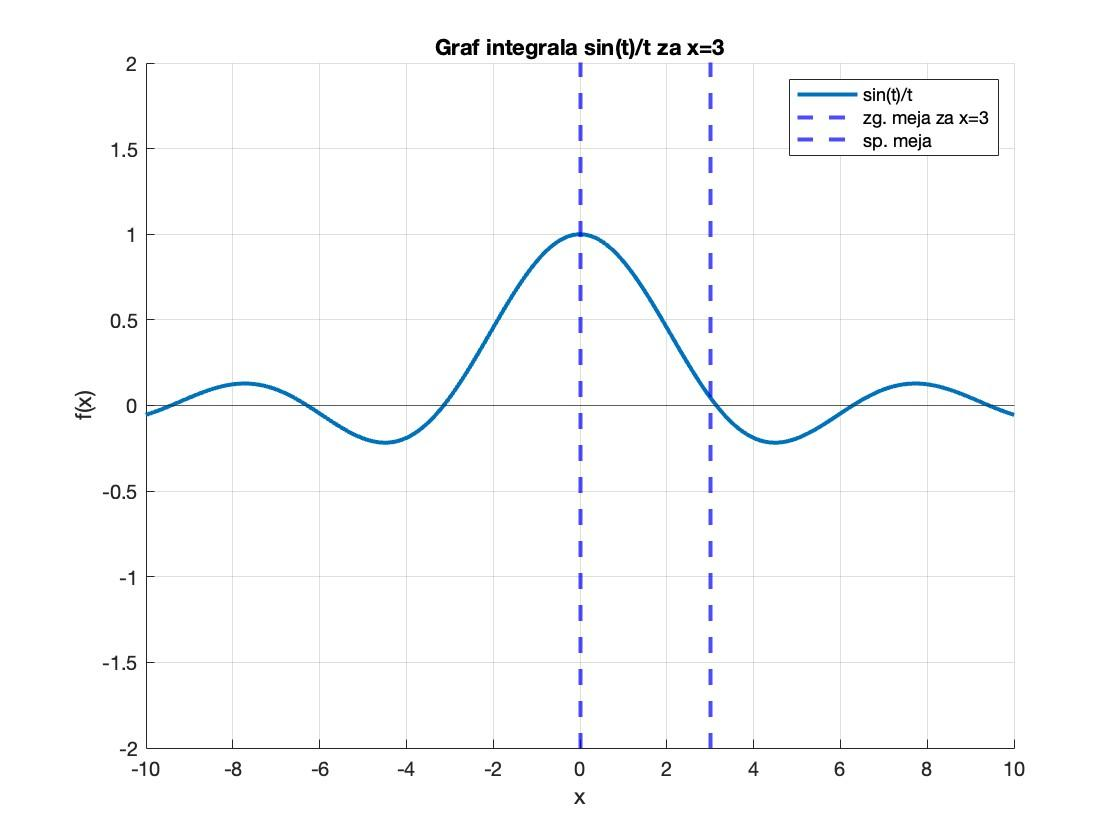

Pomagamo si s priročnikom [Abramowitz in Stegun](https://people.math.sfu.ca/~cbm/aands/page_232.htm), kjer lahko $\textrm{Si}\left(x\right)\;$zapišemo s pomožnimi funkcijami kot

$\textrm{Si}\left(x\right)=\frac{\pi }{2}-f\left(x\right)\;\cos \left(x\right)-g\left(x\right)\;\;\sin \left(x\right)$. 

Za pomožni funkciji $f\left(x\right)$ in $g\left(x\right)$ smo glede na priročnik izbrali$f\left(x\right)=\textrm{Ci}\left(x\right)\;\sin \left(x\right)-\textrm{si}\left(x\right)\;\cos \left(x\right)$ in

$g\left(x\right)=-\textrm{Ci}\left(x\right)\;\cos \left(x\right)-\textrm{si}\left(x\right)\;\sin \left(x\right)$. 

Za ovrednotenje pomožnih funkcij potrebujemo še vrednosti integralskega kosinusa $\textrm{Ci}\left(x\right)$ ter premaknjenega integralskega sinusa $\textrm{si}\left(x\right)$. Da se znebimo numeričnega računanja integrala z neskončno mejo lahko $\textrm{Ci}\left(x\right)$ in $\textrm{si}\left(x\right)$ zapišemo kot

$\textrm{Ci}\left(x\right)=\gamma +\ln \left(x\right)+\int_0^x \frac{\left(\cos \left(t\right)-1\right)}{t}\;\textrm{dt}$ , kjer je $\gamma$ Euler-Mascheroni konstanta ter

$\textrm{si}\left(x\right)=-\int_0^{\frac{\pi }{2}} e^{-x\;\cos \left(t\right)} \cos \left(x\;\sin \left(t\right)\right)\;\textrm{dt}$. Ti dve vrednosti dobimo numerično s simpsonovim pravilom za integriranje. Prva funkcija, katere integral bomo izračunali je $\frac{\left(\cos \left(t\right)-1\right)}{t}$, druga pa ${-e}^{-x\;\cos \left(t\right)} \cos \left(x\;\sin \left(t\right)\right)$. Za lažjo predstavo si ju lahko izrišemo na grafu in ogledamo meje integrala za nek izbran $x=3$.

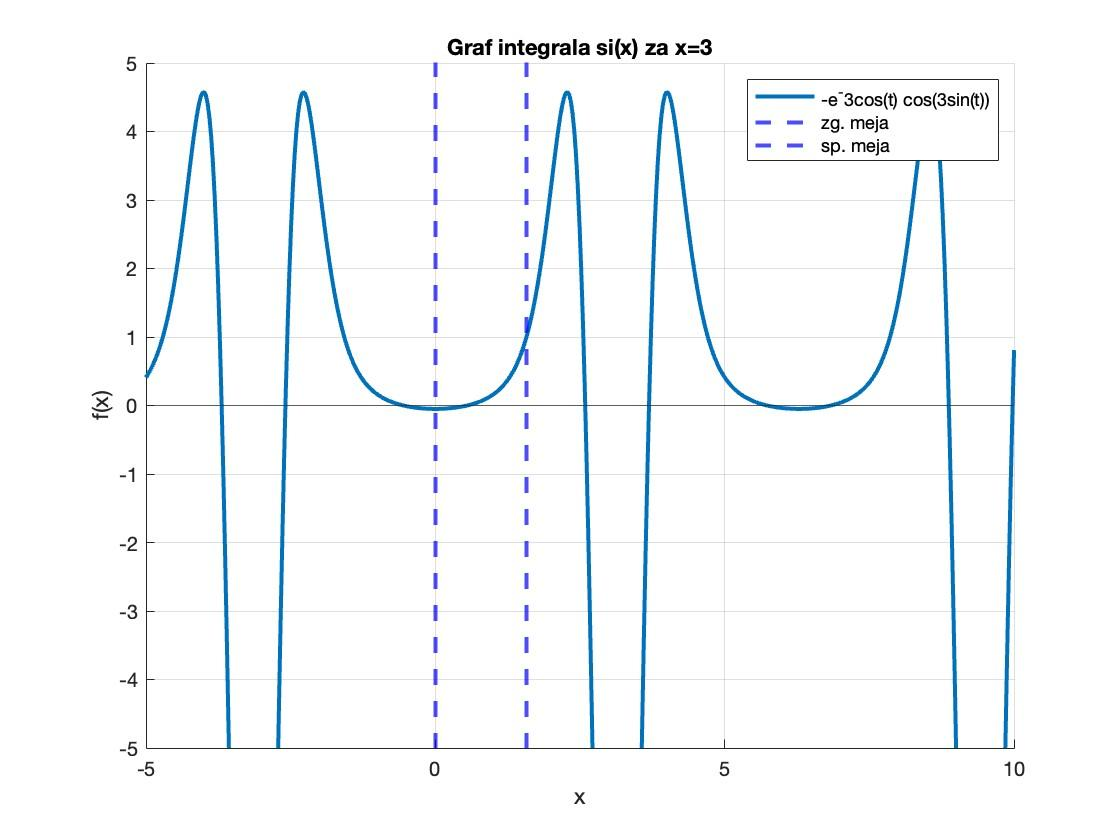

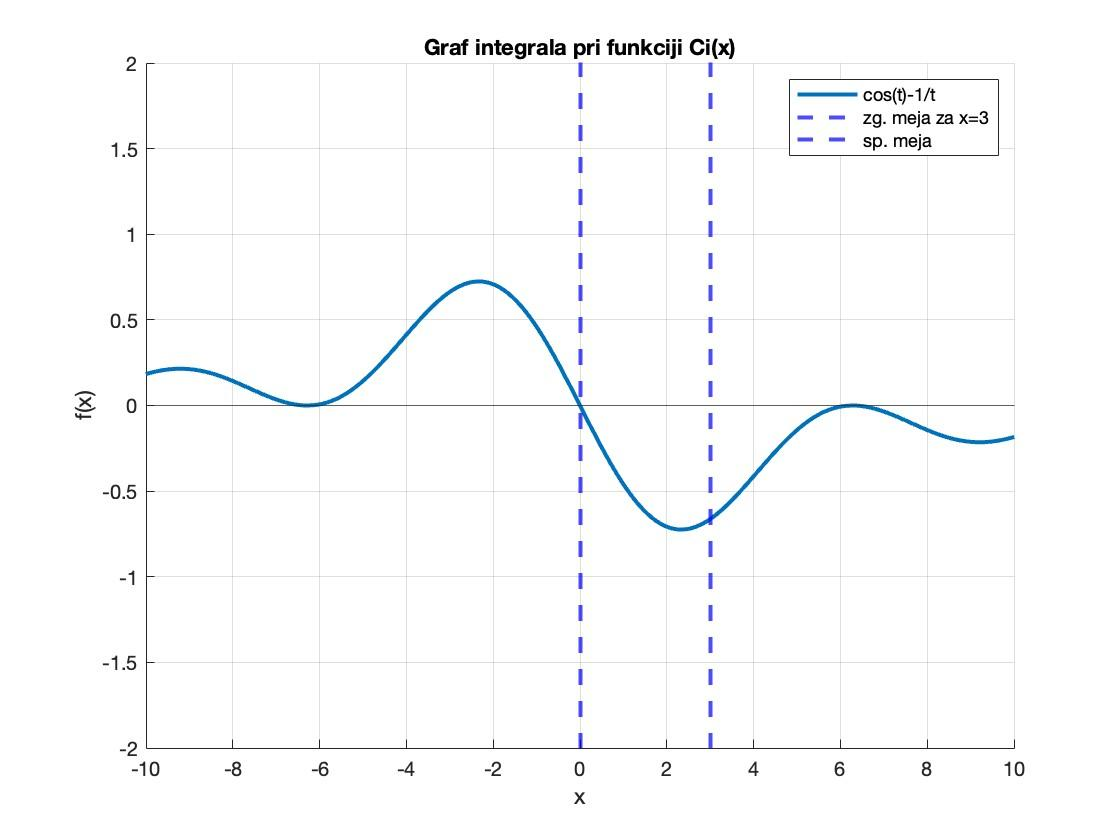

Postopek izračuna integralskega sinusa za podan $x$ je torej:

- S simpsonovim pravilom izračunamo $\textrm{Ci}\left(x\right)$ in $\textrm{si}\left(x\right)$.

- Vrednosti vstavimo v pomožni funkciji $f\left(x\right)$ in $g\left(x\right)$.

- Izračunamo $\textrm{Si}\left(x\right)$.

Na koncu lahko za boljšo primerjavo narišemo graf dejanskih vrednosti funkcije $\textrm{Si}\left(x\right)$ ter naše aproksimacije za različne zgornje vrednosti integrala, torej za različne $x$-e. Kot pričakovano se z višanjem meje povečuje absolutna vrednost napake, zanimivo pa je, da graf napake niha. Po podrobnejšem opazovanju lahko sklepamo, da je gibanje posledica računanja aproksimacije pomožnih funkcij s simpsonovo metodo ter izbira dolžine intervala, na katerega računamo vrednosti $x$. Največje napake so namreč, ko je meja $x$ na vrhu periode grafa $\frac{\left(\cos \left(t\right)-1\right)}{t}$ ter na lokalnih maksimumih grafa $\textrm{si}\left(x\right)$, najnižje pa ko je $x$ blizu ničle pri obeh grafih, saj takrat ujamemo celotno periodo in jo je lažje aproksimirati s parabolo pri simpsonovi metodi.

Napaka je tudi odvisna od števila korakov pri simpsonovi metodi, kjer za napako na manj kot 10 decimalk pri visokih vrednostih $x$-a potrebujemo že okoli 10 000 korakov za uspešni približek, za enako napako pri nizkih vrednosti $x$-a (npr za $x=0\ldotp 1$) pa zgolj 50.

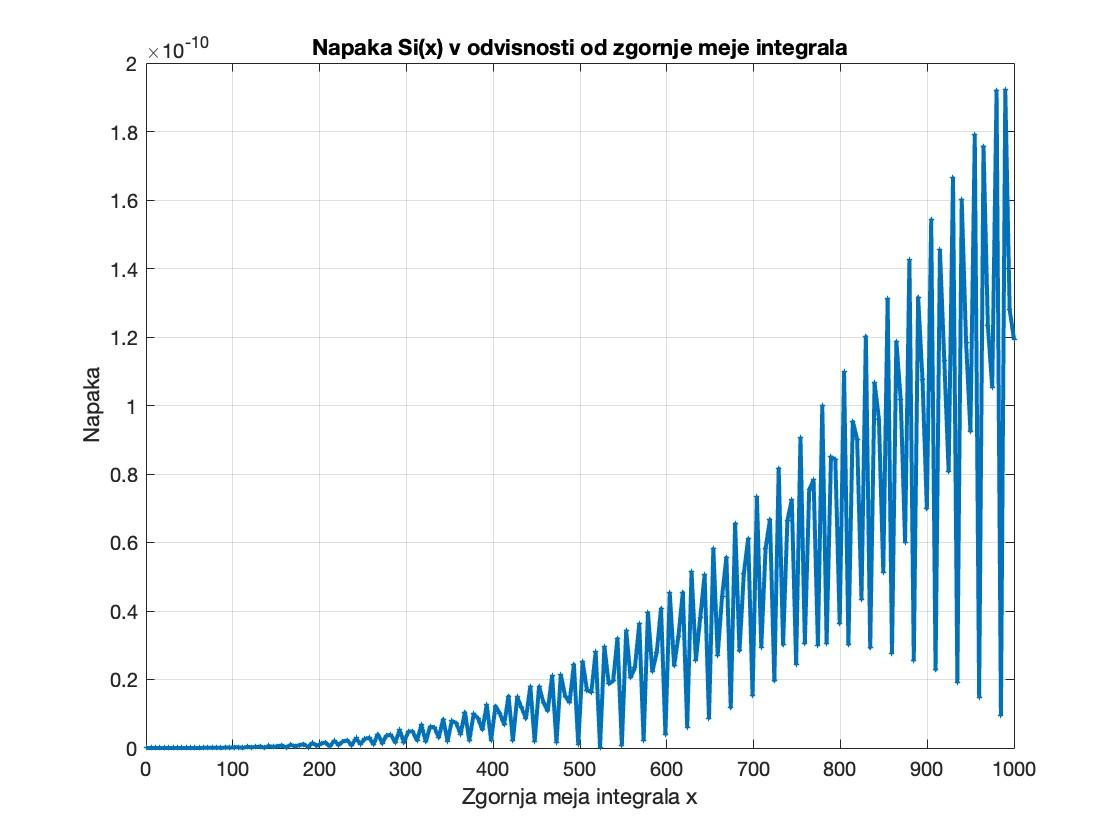

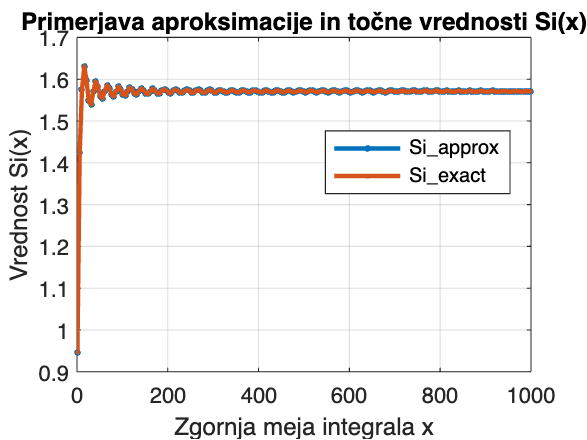


% Definirajmo funkcijo za točno vrednost Si(x)
true_Si = @(x) integral(@(t) sin(t)./t, 0, x, 'ArrayValued', true);

% Seznam različnih zgornjih mej x za integral, od 1 do 1000 v 200 korakih
x_values = linspace(1, 1000, 200);

Si_approx_values = zeros(size(x_values));
Si_exact_values = zeros(size(x_values));

% Izračun aproksimacij in točnih vrednosti za vsak x
for i = 1:length(x_values)
    current_x = x_values(i);
    Si_approx_values(i) = aproksimiraj_Si(current_x,10000);
    Si_exact_values(i) = true_Si(current_x);
end

% Graf primerjave dejanskih vrednosti in nase aproksimacije
figure;
plot(x_values, Si_approx_values, '-o', 'LineWidth', 2, 'DisplayName', 'Si\_approx', 'MarkerSize', 1);
hold on;
plot(x_values, Si_exact_values, '-x', 'LineWidth', 2, 'DisplayName', 'Si\_exact','MarkerSize', 1);
hold off;
xlabel('Zgornja meja integrala x');
ylabel('Vrednost Si(x)');
title('Primerjava aproksimacije in točne vrednosti Si(x)');
legend('Location', 'Best');
grid on;

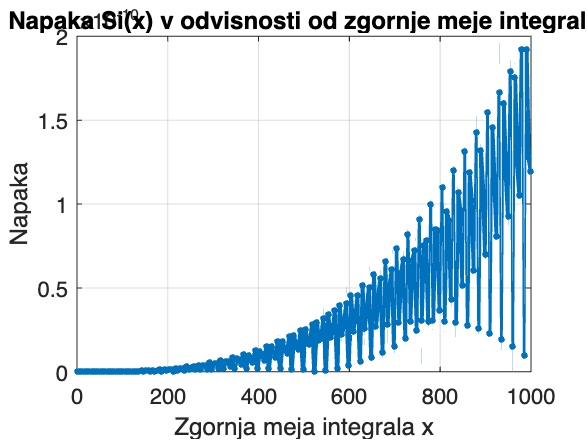


% Graf absolutne vrednosti napake glede na razlicne vrednosti zgornje meje x
figure;
errors = abs(Si_approx_values - Si_exact_values);
plot(x_values, errors, '-o', 'LineWidth', 2,'MarkerSize', 1);
xlabel('Zgornja meja integrala x');
ylabel('Napaka');
title('Napaka Si(x) v odvisnosti od zgornje meje integrala');
grid on;

## Ploščina hipotrohoide 

Cilj naloge je izračunati površino, ki jo omejuje hipotrohoida s parametri $a=1$ in $b=-\frac{11}{7}$. Enačba hipotrohoide je podana parametrično kot funkcija $t$-ja:

$\begin{array}{l}
x\left(t\right)=\left(a+b\right)\;\cos \left(t\right)-b\;\cos \left(\frac{a+b}{b}\;t\right)\\
y\left(t\right)=\left(a+b\right)\;\sin \left(t\right)-b\;\sin \left(\frac{a+b}{b}\;t\right)
\end{array}$.

Površino hipotrohoide bomo izračunali s pomočjo formule za površino krivočrtnega trikotnika pod krivuljo. Ploščina je 

$P=\frac{1}{2}\int_{\textrm{t1}}^{\textrm{t2}} \left(x\left(t\right)\;\dot{y} \left(t\right)-\dot{x} \left(t\right)y\left(t\right)\;\right)\;\textrm{dt}$,

kjer $u\left(t\right)=\left(x\left(t\right),y\left(t\right)\right)$ predstavlja parametricno krivuljo, v našem primeru hipotrohoido.

Opazimo namreč lahko, da je hipotrohoida sestavljena iz sedem enakih krivovčrtanih trikotnikov, ki jih zgoraj omejuje lok hipotrohoide. Ugotoviti moramo le parametre $\textrm{t1}$ in $\textrm{t2}$, torej pri katerem $t$ se lok hipotrohoide začne in pri katerem se konča.

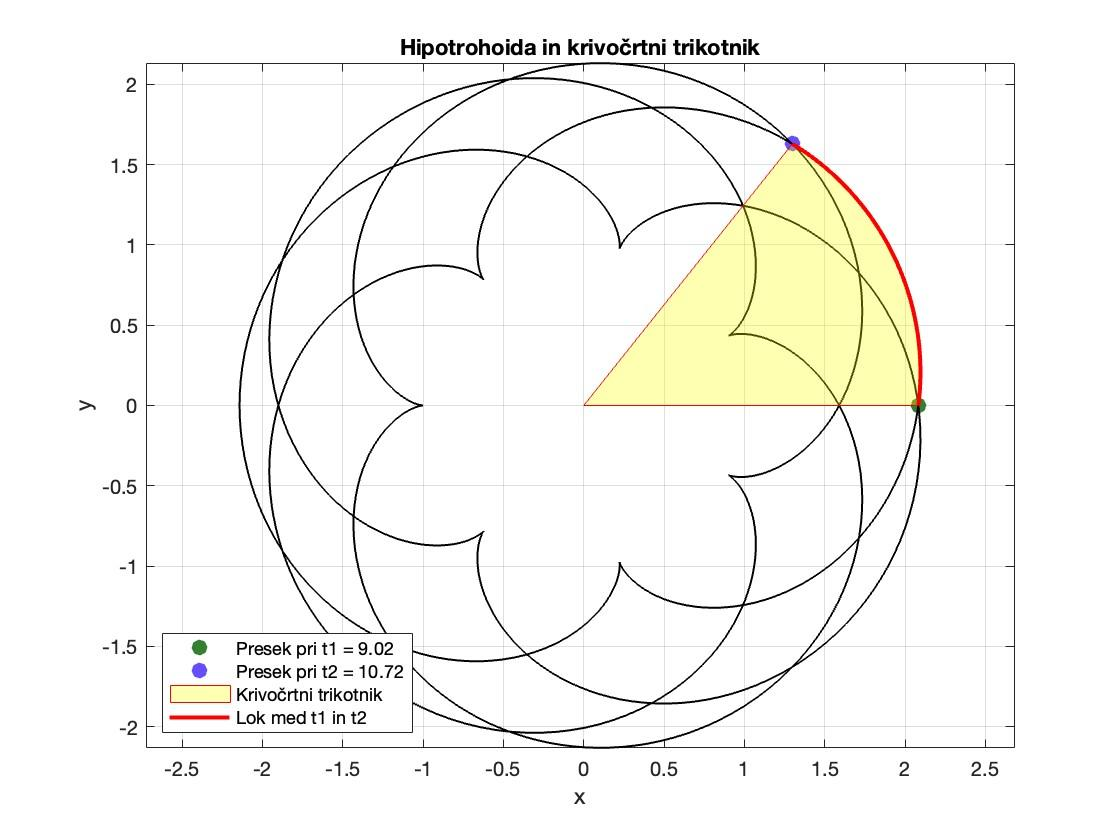

Da dobimo $\mathrm{t1}$ moramo izračunati presečišče hipotrohoide z x osjo, iščemo torej $t$, pri katerem je $y\left(t\right)=0$. 

Za računanje $\textrm{t1}$rešujemo sistem z eno enačbo, za $\textrm{t2}$ pa je sitaucija malo težja, saj iščemo presečišče s premico pod kotom $\frac{2\pi }{7}$. Če premico zapišemo v parametrični obliki dobimo


$$x_{\textrm{premica}} \left(r\right)=r\;\cos \left(\frac{2\pi }{7}\right)$$
 

$y_{\textrm{premica}} \left(r\right)=r\;\sin \left(\frac{2\pi }{7}\right)$.

Za računanje presečišča dobimo tako sistem dveh nelinearnih enačb z dvema neznankamama, parametrom $t$ ter $r$:


$$\left(a+b\right)\;\cos \left(t\right)-b\;\cos \left(\frac{a+b}{b}\;t\right)=r\;\cos \left(\frac{2\pi }{7}\right)$$



$$\left(a+b\right)\;\sin \left(t\right)-b\;\sin \left(\frac{a+b}{b}\;t\right)=r\;\sin \left(\frac{2\pi }{7}\right)$$


Za reševanje obeh presečišč smo uporabili Newtonovo iteracijo, ki najde približke ničel sistema nelinearnih enačb, tako da aproksimira funkcijo s tangento in išče presečišče tangente z x osjo ter postopek ponavlja. Glede na to da lahko odvode izračunamo analitično, smo fukcijo prilagodili tako, da kot argumente že sprejme odvode in je prilagojena za reševanje zgolj dveh nelinearnih enačb.

Dobljena presečišča $\textrm{t1}$in $\textrm{t2}$ nato vstavimo za mejo integrala pri računanju ploščine krivočrtnega trikotnika, kjer integral aproksimiramo s simpsonovo metodo. Dobimo plošičino ${\textrm{pl}}_{\textrm{trikotnika}} =2\ldotp 0225997018$, ki jo nato množimo s 7 in dobimo ${\mathrm{pl}}_{\mathrm{hipotrohoide}} =14\ldotp 1581979130\ldotp$

Pridobljene rezultate sicer ne moramo analitično testirati, a lahko dobimo približno oceno površine. Za testiranje smo narisali dva kroga, ki obdajata hipotrohoido. Prvi z $r_1 =2\ldotp 130$, ki očrta hipotrohoido in seže do njene zgornje meje, drugi pa s polmerjem $r_2 =2\ldotp 083$, ki sega do konca loka krivočrtnega trikotnika. Ploščina hipotrohoide bi morala biti med tema dvema krogoma, torej med $\pi r_1^2 =14\ldotp 2531$ in $\pi r_2^2 =13\ldotp 6310$. Kot vidimo je ${\textrm{pl}}_{\textrm{hipotrohoide}} =14\ldotp 1582$ torej v mejah obeh krogov. 

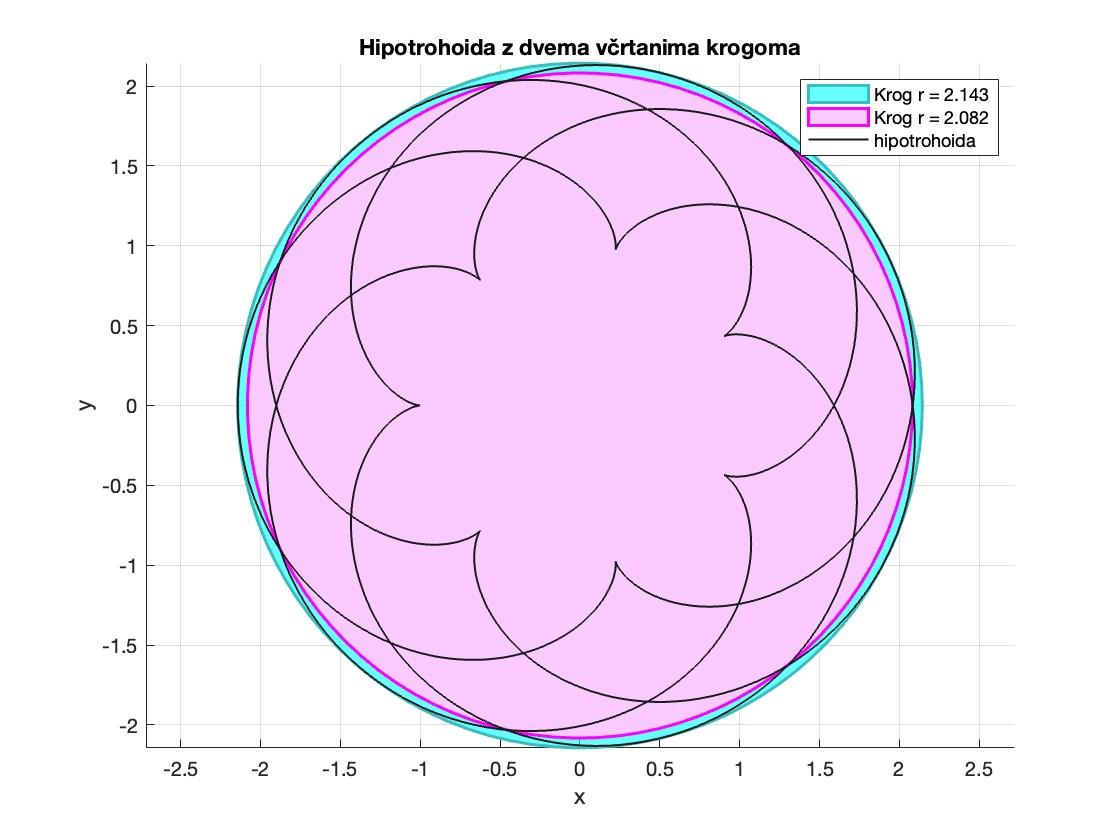

[pl_hipo, pl_trikotnika, t1, t2] = pl_hipotrohoide();

fprintf('Ploščina krivočrtnega trikotnika: %.10f\n', pl_trikotnika);

Ploščina krivočrtnega trikotnika: 2.0225996558


fprintf('Ploščina hipotrohoide: %.10f\n', pl_hipo);

Ploščina hipotrohoide: 14.1581975906


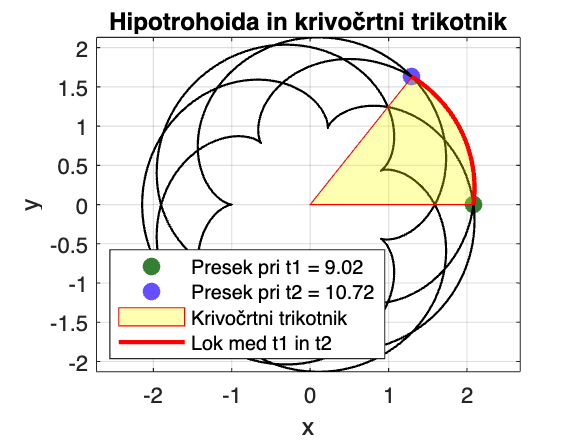



% GRAFI 
% Graf hipotrohoide in krivocrtnega trikotnika
a = 1;
b = -11/7;
theta = 2*pi/7;

x = @(t) (a + b) * cos(t) + b * cos((a + b) / b * t);
y = @(t) (a + b) * sin(t) + b * sin((a + b) / b * t);

x_intersect_x_axis = x(t1);
y_intersect_x_axis = y(t1);

figure;
t_values = linspace(t1, t2, 100);
x_arc = x(t_values);
y_arc = y(t_values);
x_intersect_line = x(t2);
y_intersect_line = y(t2);
polygon_x = [0, x_intersect_x_axis, x_arc];
polygon_y = [0, y_intersect_x_axis, y_arc];

plot(x_intersect_x_axis, 0, 'o', 'MarkerSize', 8, 'MarkerFaceColor', [0.2 0.5 0.2], 'MarkerEdgeColor', 'none'); % Dark green dot for x-axis intersection
hold on;
plot(x_intersect_line, y_intersect_line, 'o', 'MarkerSize', 8, 'MarkerFaceColor', [0.4 0.3 1], 'MarkerEdgeColor', 'none'); % Dark blue dot for line intersection
hold on;

fplot(x, y, [0 22*pi], 'black-', 'LineWidth', 1);
hold on;
fill(polygon_x, polygon_y, 'yellow', 'FaceAlpha', 0.3, 'EdgeColor', 'red');
plot(x_arc, y_arc, 'red-', 'LineWidth', 2);

xlabel('x');
ylabel('y');
title('Hipotrohoida in krivočrtni trikotnik');
axis equal;
grid on;
legend('Presek pri t1 = 9.02', 'Presek pri t2 = 10.72', '', 'Krivočrtni trikotnik', 'Lok med t1 in t2','Location', 'southwest');

% Graf hipotrohoide in dveh vcrtanih krogov za testiranje
hold off;

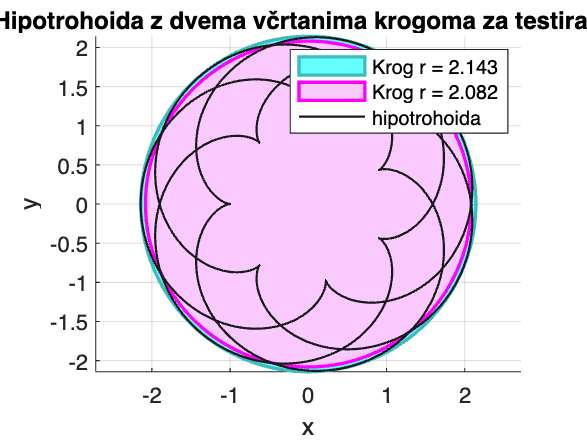


r1 = 2.143;
r2 = 2.082;
theta_circle = linspace(0, 2*pi, 100);

% Krog 1 (r = 2.143)
x_circle1 = r1 * cos(theta_circle);
y_circle1 = r1 * sin(theta_circle);

% Krog 2 (r = 2.082)
x_circle2 = r2 * cos(theta_circle);
y_circle2 = r2 * sin(theta_circle);

figure;
hold on;

t_values = linspace(0, 22*pi, 1000);
x_hypo = x(t_values);
y_hypo = y(t_values);

fill(x_circle1, y_circle1, 'cyan', 'FaceAlpha', 0.6, 'EdgeColor', [0.23, 0.74, 0.74], 'LineWidth', 1.5);
fill(x_circle2, y_circle2, [0.98 0.79 1], 'FaceAlpha', 1, 'EdgeColor', 'magenta', 'LineWidth', 1.5);
plot(x_hypo, y_hypo, 'Color', [0.1, 0.1, 0.1], 'LineWidth', 1); % Grey color

xlabel('x');
ylabel('y');
title('Hipotrohoida z dvema včrtanima krogoma za testiranje');
axis equal;
grid on;
legend('Krog r = 2.143', 'Krog r = 2.082', 'hipotrohoida');
hold off;